# Yalmip solution for Regional pole placement

clear all ; close all ;

## Motor Parameters and model

 
model.R = 0.656;         % Ohm
model.L = 0.35e-3;       % H
model.Phif = 6.6e-3;     % Wb
model.p = 4;
model.F = 1.e-05;
model.J = 1e-05;
disp(model);

       R: 0.6560
       L: 3.5000e-04
    Phif: 0.0066
       p: 4
       F: 1.0000e-05
       J: 1.0000e-05




% State space representation of the motor model

A = [-model.R/model.L -model.p*model.Phif ; 3*model.p*model.Phif/(2*model.J) -model.F/model.J ];
B = [1/model.L;0];
C = [0 1];
n=size(A,1); 
% Augmented model with integral action
A = [A zeros(n,1);-C 0] ; 
B=[B;0]; 
%Bw=[eye(3)]; Duz=1; Cz=[0 0 0]; Dwz=[0; 0; 0];
n=size(A,1); m=size(B,2);

## Optimization problem

 
alpha =330;
beta =1.6 ;
alphamax = 3* alpha ;
tol = 1e-3;
warning('off')
X=sdpvar(n);Y=sdpvar(m,n);
F = [X >= tol*eye(n)];
F = F + [-B*Y-Y'*B'-2*alpha*X-X*A'-A*X>= tol*eye(n) ] ;
F = F + [B*Y+Y'*B'+2*alphamax*X+X*A'+A*X>= tol*eye(n) ] ; 
F = F + [-[beta*(X*A'+A*X)  A*X-X*A'; (A*X-X*A')'  beta*(X*A'+A*X)]-...
        [beta*(Y'*B'+B*Y)  B*Y-Y'*B'; ( B*Y-Y'*B')'  beta*(Y'*B'+B*Y)] >= tol*eye(2*n) ] ; 
OPTIONS = sdpsettings('verbose',0) ;
sol=solvesdp(F,'',OPTIONS) ;
X=double(X) ; Y=double(Y) ;K =Y*X^(-1) ;eig_A_BK = eig(A+B*K); 
disp(['K=[' num2str(K) ']'])

K=[0.0455429    -0.150935      38.6082]


disp(['eig_A_BK=[' num2str(eig_A_BK') ']'])

eig_A_BK=[-692.04895-854.91979i          -692.04895+854.91979i                   -361.0653+0i]


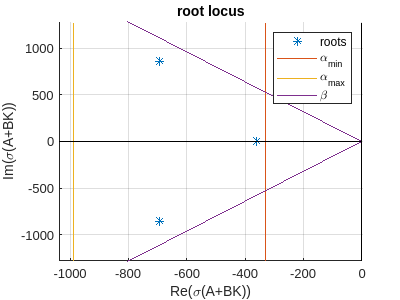


figure;clf;
xmin = 1.5*min(real(eig_A_BK)); xmax = 1; ymin = 1.5*min(imag(eig_A_BK)); ymax = 1.5*max(imag(eig_A_BK));
hold on
grid on
plot(real(eig_A_BK),imag(eig_A_BK),'*')
plot([-alpha -alpha],[ymin ymax])
plot([-alphamax -alphamax],[ymin ymax])
plot([-alphamax 0],[alphamax*beta 0],'color','#7E2F8E')
plot([-alphamax 0],[-alphamax*beta 0],'color','#7E2F8E')
plot([0 0],[ymin ymax],'k')
plot([xmin xmax],[0 0],'k')
axis([xmin xmax ymin-1 ymax+1])
title('root locus')
xlabel('Re(\sigma(A+BK))')
ylabel('Im(\sigma(A+BK))')
legend('roots','\alpha_{min}','\alpha_{max}','\beta')